# Iterative Control Example

## Model setting

T = 100; % Total time
% System matrix
A= [-0.8 -0.22 ;
    1 0];  % System matrix
B=[0.5;1]; 
C=[1 0.5];
G=tf(ss(A,B,C,[],1));

## Initial iteration

 ,  

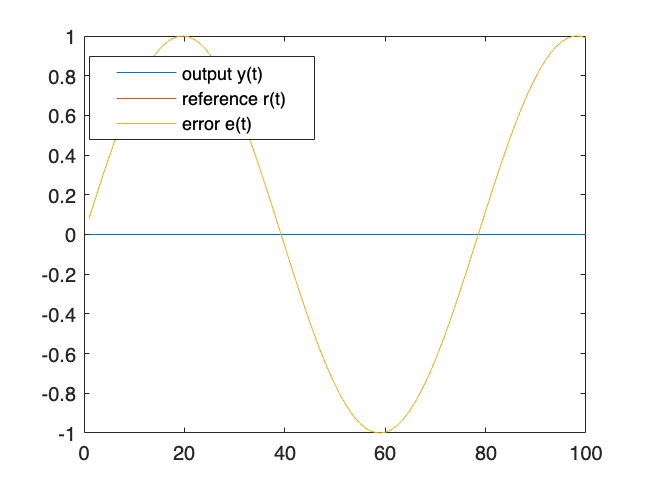

u_1 = zeros(1,T); % Initial input signal
% r = [zeros(T/2,1) ; 1*ones(T/2,1)]; % Reference signal (desired output)
r = sin(8/100*linspace(1,100))';

% The function "simul" simulates the output of a filter G with input u
y_1 = simul(G,u_1); % System output
e_1 = r - y_1; % Initial error

% Initial iteration results:
figure(1)
plot(y_1)
hold on
plot(r)
plot(e_1)
legend(["output y(t)", "reference r(t)", "error e(t)"], "Position", [0.1372 0.7112 0.3494, 0.1733])

%% ILC

% Filters:
gamma =0.5

gamma = 0.5000


iter = 5; % Number of ILC iterations

% Store output:
u = zeros(T,iter+1);
u(:,1) = u_1;
y = zeros(T,iter+1);
y(:,1) = y_1;
e = zeros(T,iter+1);
e(:,1) = e_1;


## ILC Main loop

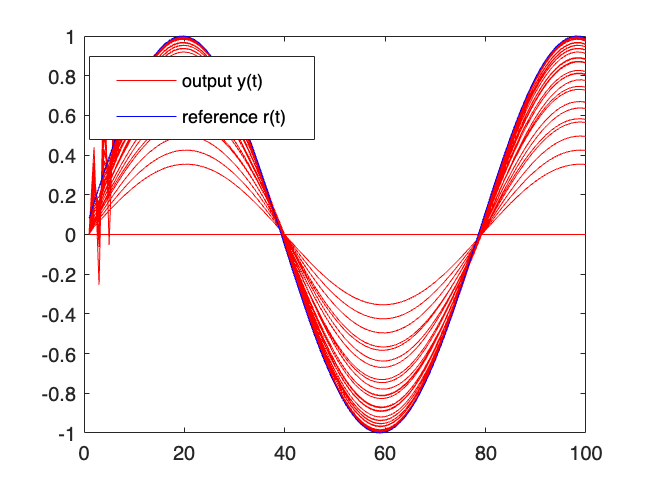

for k = 1:iter
    %%% Implement ILC here! %%%
u(:,k+1)=u(:,k)+ gamma*e(:,k);
y(:,k+1)= simul(G,u(:,k+1));
e(:,k+1)=r-y(:,k+1);
end

% Plotting the result:
for i = 1:iter+1
    figure(2)
    plot(y(:,i),'r');
    hold on
    plot(r,'b')
    % plot(e(:,i));
    legend(["output y(t)", "reference r(t)"], "Position", [0.1372 0.7112 0.3494, 0.1733])
     % pause();
end